# NDCG@5

% Load data
load C:\Users\Andrea\Desktop\MAGISTRALE\Anno1-sem2\SearchEngines\HWS\seupd2021-goldr\RUN\RUN2020\RunAnalysis\runtotonlyndcg5.mat

measure_ndcg5 = runtotonlyndcg5(1:49,:);
measure_ndcg5 = table2array(measure_ndcg5)

measure_ndcg5 =     1.0000    1.0000    1.0000    1.0000    1.0000
    0.6844    0.6844    0.6844    0.6844    0.6992
    0.5258    0.5258    0.5258    0.5920    0.5920
    0.8688    0.7227    0.8688    0.1696    0.1696
    0.6844    0.6844    0.6844         0         0
    0.4852    0.5087    0.4852    0.0848    0.0848
    0.8539    0.7227    0.8539    0.6399    0.6399
    0.4704    0.4704    0.4704         0         0
    0.8539    0.7227    0.8539    0.3601    0.5296
    0.8539    0.6548    0.8539    0.3392    0.6548



% remove the now useless ap matrix
clear runtotonlyndcg5;

% the significance level
alpha = 0.05;

% the mean for each run across the topics
m_avg_ndcg5 = mean(measure_ndcg5);

ogmyruns = "";
ogmyruns(1) = "run1";
ogmyruns(2) = "run2";
ogmyruns(3) = "run3";
ogmyruns(4) = "run4";
ogmyruns(5) = "run5";

myruns_ndcg5 = ogmyruns;

% sort in descending order of mean score
[~, idx] = sort(m_avg_ndcg5, 'descend');

% re-order runs by descending mean of the measure
measure_ndcg5 = measure_ndcg5(:, idx);
myruns_ndcg5 = myruns_ndcg5(:,idx);

## One way ANOVA

% perform the ANOVA
[~, tbl_ndcg5, sts_ndcg5] = anova1(measure_ndcg5, myruns_ndcg5, 'off');

% display the ANOVA table
tbl_ndcg5

tbl_ndcg5 = 4×6 cell array
    {'Source' }    {'SS'     }    {'df' }    {'MS'      }    {'F'       }    {'Prob>F'    }
    {'Columns'}    {[ 2.1162]}    {[  4]}    {[  0.5290]}    {[  7.6877]}    {[7.6237e-06]}
    {'Error'  }    {[16.5160]}    {[240]}    {[  0.0688]}    {0×0 double}    {0×0 double  }
    {'Total'  }    {[18.6321]}    {[244]}    {0×0 double}    {0×0 double}    {0×0 double  }


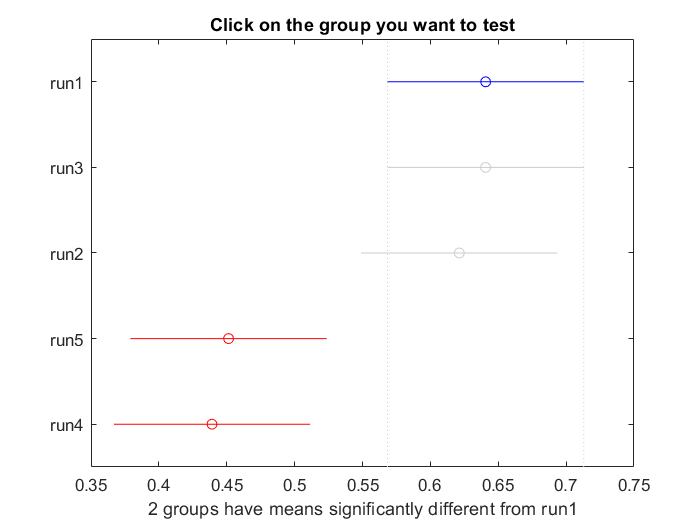


c = multcompare(sts_ndcg5, 'Alpha', alpha, 'Ctype', 'hsd'); 

c

c =     1.0000    2.0000   -0.1446         0    0.1446    1.0000
    1.0000    3.0000   -0.1252    0.0194    0.1640    0.9962
    1.0000    4.0000    0.0448    0.1894    0.3339    0.0033
    1.0000    5.0000    0.0570    0.2016    0.3461    0.0013
    2.0000    3.0000   -0.1252    0.0194    0.1640    0.9962
    2.0000    4.0000    0.0448    0.1894    0.3339    0.0033
    2.0000    5.0000    0.0570    0.2016    0.3461    0.0013
    3.0000    4.0000    0.0254    0.1700    0.3145    0.0117
    3.0000    5.0000    0.0376    0.1822    0.3267    0.0053
    4.0000    5.0000   -0.1324    0.0122    0.1568    0.9994


## Two way ANOVA

% perform the ANOVA
[~, tbl2_ndcg5, sts2_ndcg5] = anova2(measure_ndcg5, 1,'off');

% display the ANOVA table
tbl2_ndcg5

tbl2_ndcg5 = 5×6 cell array
    {'Source' }    {'SS'     }    {'df' }    {'MS'      }    {'F'       }    {'Prob>F'    }
    {'Columns'}    {[ 2.1162]}    {[  4]}    {[  0.5290]}    {[ 28.4808]}    {[1.3911e-18]}
    {'Rows'   }    {[12.9495]}    {[ 48]}    {[  0.2698]}    {[ 14.5235]}    {[1.0785e-42]}
    {'Error'  }    {[ 3.5665]}    {[192]}    {[  0.0186]}    {0×0 double}    {0×0 double  }
    {'Total'  }    {[18.6321]}    {[244]}    {0×0 double}    {0×0 double}    {0×0 double  }


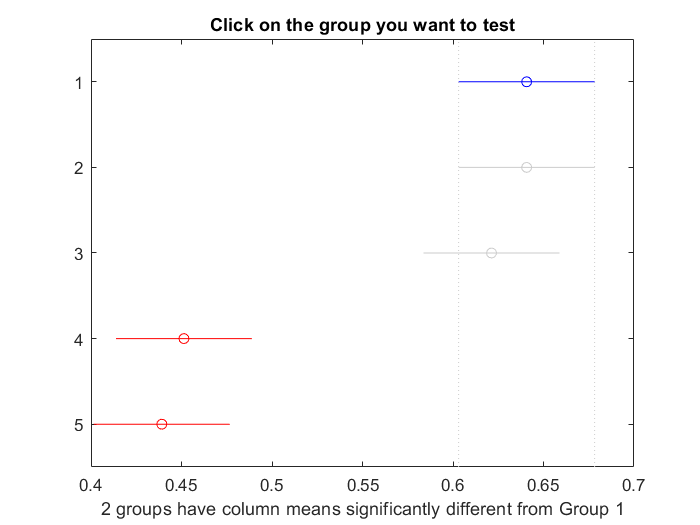


c2 = multcompare(sts2_ndcg5, 'Alpha', alpha, 'Ctype', 'hsd',"Estimate","column"); 

c2

c2 =     1.0000    2.0000   -0.0751         0    0.0751    1.0000
    1.0000    3.0000   -0.0557    0.0194    0.0945    0.9555
    1.0000    4.0000    0.1142    0.1894    0.2645    0.0000
    1.0000    5.0000    0.1265    0.2016    0.2767    0.0000
    2.0000    3.0000   -0.0557    0.0194    0.0945    0.9555
    2.0000    4.0000    0.1142    0.1894    0.2645    0.0000
    2.0000    5.0000    0.1265    0.2016    0.2767    0.0000
    3.0000    4.0000    0.0948    0.1700    0.2451    0.0000
    3.0000    5.0000    0.1071    0.1822    0.2573    0.0000
    4.0000    5.0000   -0.0629    0.0122    0.0873    0.9920


## BoxPlot

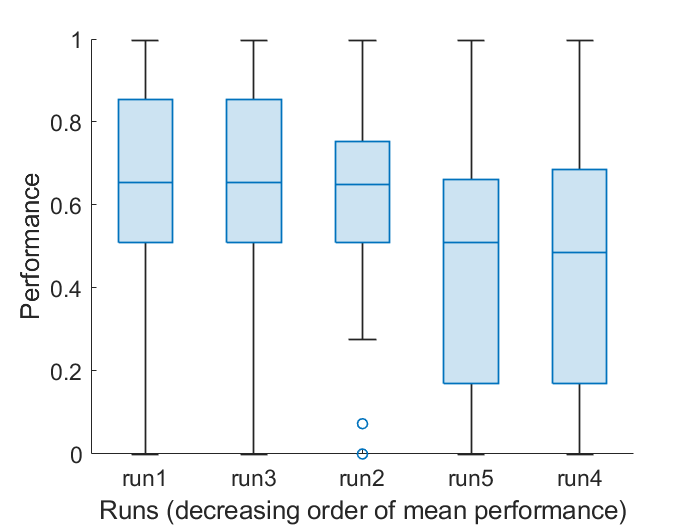

% Compute the mean performance of each run across topics
m_ndcg5 = mean(measure_ndcg5);
myruns4 = ogmyruns;

% sort in descending order of mean score
[~, idx] = sort(m_ndcg5, 'descend');

% re-order runs by descending mean of the measure
% needed to have a more nice looking box plot
measure_ndcg5 = measure_ndcg5(:, idx);
myruns4 = myruns_ndcg5(:,idx);

figure

% show the box plot
boxchart(measure_ndcg5)

%hold on

% plot the mean on top of the box plot
%plot (m, ':x', "MarkerSize", 10, "LineWidth", 2)

% adjust tick labels on x-axis, y-axis range, and font size
ax = gca;
ax.FontSize = 14;
ax.XTickLabel = myruns4;

xlabel("Runs (decreasing order of mean performance)")
ylabel("Performance")

newmeasure_n = measure_ndcg5(:, [1,3,2,5,4]);

Run run1 vs run2: p-value 0.054621

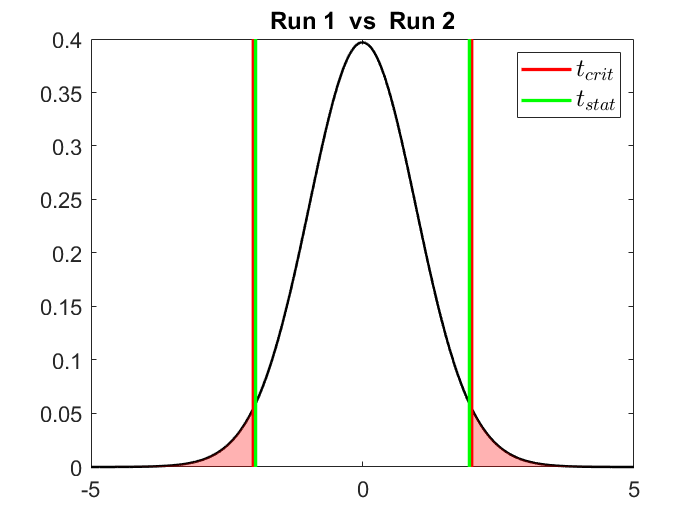

Run run1 vs run3: p-value NaN

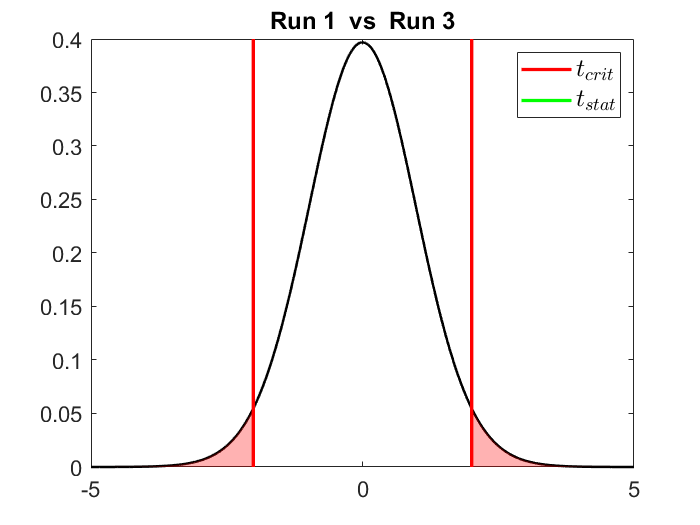

Run run1 vs run4: p-value 0.000001

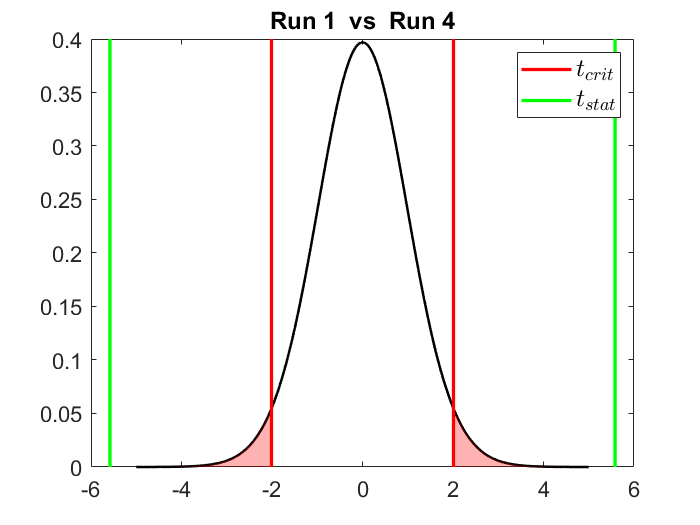

Run run1 vs run5: p-value 0.000001

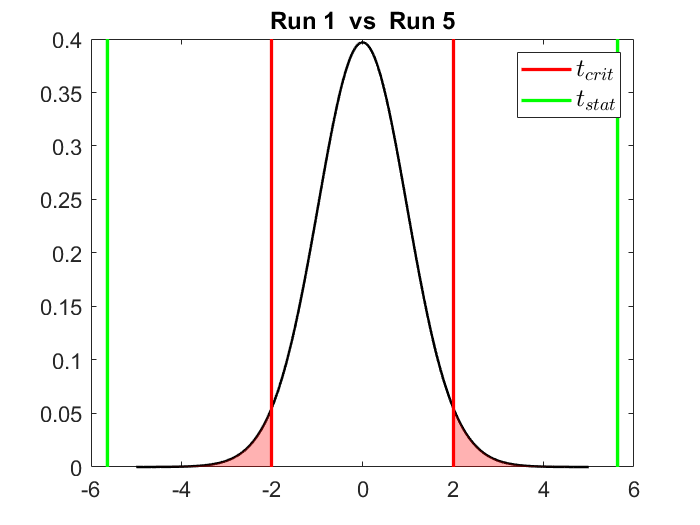

Run run2 vs run3: p-value 0.054621

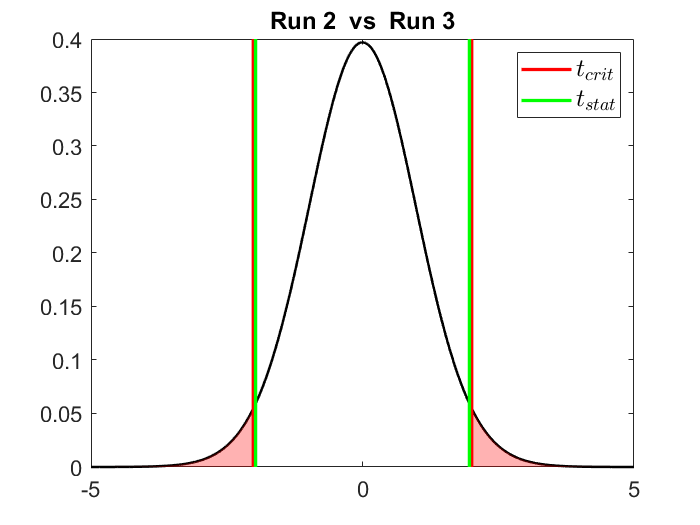

Run run2 vs run4: p-value 0.000006

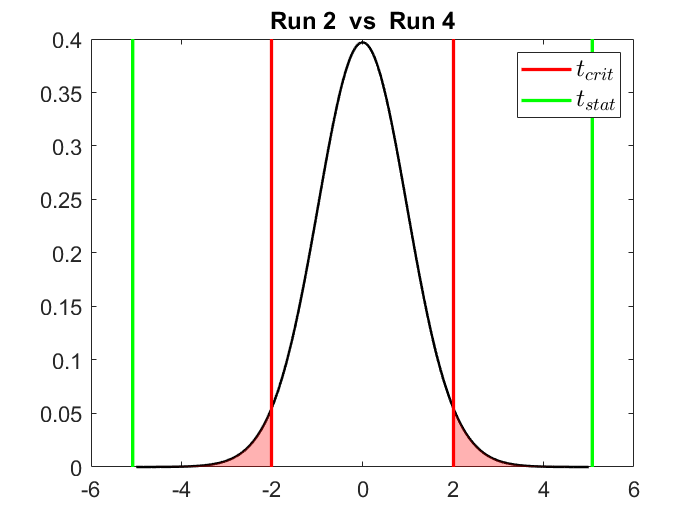

Run run2 vs run5: p-value 0.000009

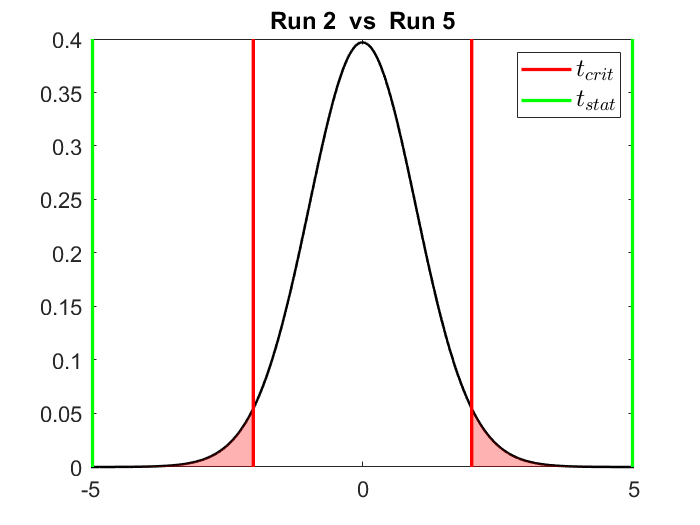

Run run3 vs run4: p-value 0.000001

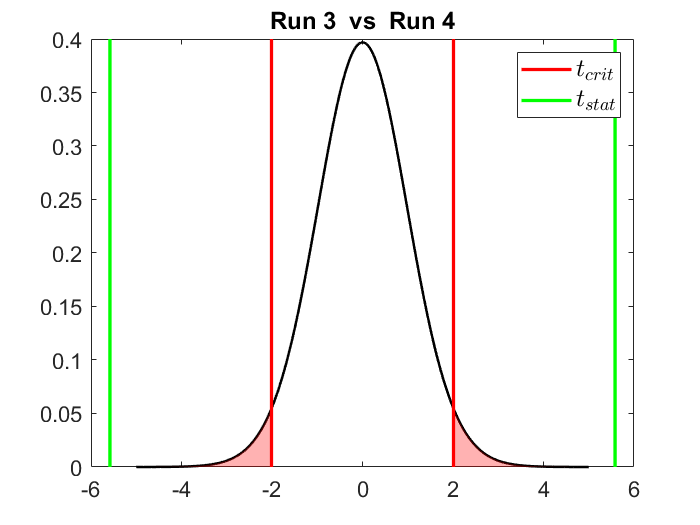

Run run3 vs run5: p-value 0.000001

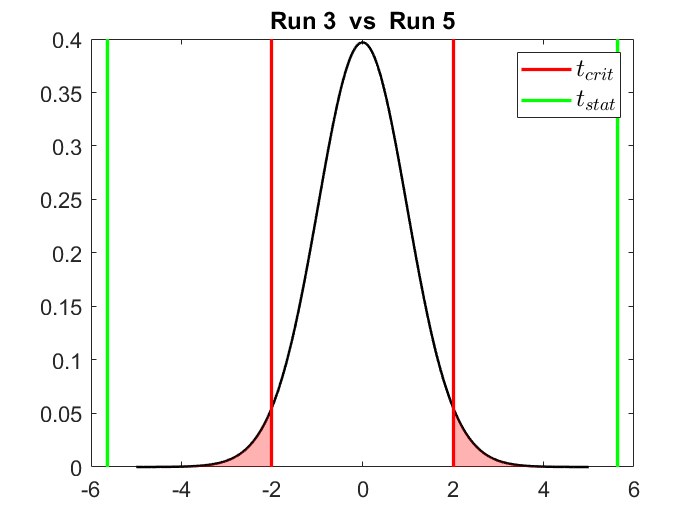

Run run4 vs run5: p-value 0.143588

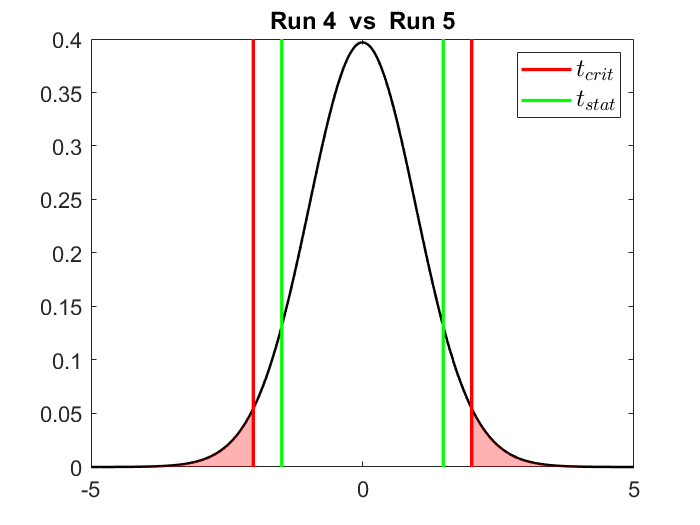

for r1 = 1:5
    for r2 = 1:5
        if r1 < r2
            %tstudnet comparisons
            [~, p] = ttest(newmeasure_n(:, r1), newmeasure_n(:, r2));
            %p(isnan(p))=0;
            fprintf("Run %s vs %s: p-value %f", ogmyruns(r1), ogmyruns(r2), p)
            
            df = length(newmeasure_n) - 1;
            tCrit = tinv(1 - 0.05/2, df);
            tRuns = tinv(1 - p/2, df);
            %if p == 0
             %   tRuns = 10;
            %else
            %    tRuns = tinv(1 - p/2, df);
                %fprintf("tRuns: " + tRuns)
            %end

            % t distribution 
            ar = -5:.01:5;
            ts = tpdf(ar, df);

            % find where we are above and below tCrit
            idx1 = ar >= tCrit;
            idx2 = ar <= -tCrit;
            
            figure

            plot(ar, ts, "LineWidth", 1.5, "Color", "k");
            
            hold on

            % plot two vertical lines corresponding to tCrit
            h(1) = plot([tCrit tCrit], get(gca, "ylim"), "Color", "r", "LineWidth", 2, "LineStyle", "-");
            plot([-tCrit -tCrit], get(gca, "ylim"), "Color", "r", "LineWidth", 2, "LineStyle", "-");

            % color the area under the t distribution above and below tCrit
            area(ar(idx1), ts(idx1) , "FaceColor", "r", "FaceAlpha", 0.3, "EdgeColor", "none");
            area(ar(idx2), ts(idx2), "FaceColor", "r", "FaceAlpha", 0.3, "EdgeColor", "none");
            
            h(2) = plot([tRuns tRuns], get(gca, "ylim"), "Color", "g", "LineWidth", 2, "LineStyle", "-");
            plot([-tRuns -tRuns], get(gca, "ylim"), "Color", "g", "LineWidth", 2, "LineStyle", "-");
            %xline(tRuns, "Color", "g", "LineWidth", 2);

            ax = gca;
            ax.FontSize = 13;
            title(['Run ',num2str(r1),'  vs  Run ',num2str(r2)])
            
            lgnd = legend([h(1), h(2)], ["$t_{crit}$", "$t_{stat}$"], "Interpreter", "Latex");
            lgnd.FontSize = 15;
            
            %fprintf("%d - %d \n", r1, r2)
            if r2 == 5
                break
            end
        end
    end
end